## **Practical Problems 2 - Plotting & Programming**

1. Plot the exponential function between *x* = -10 and 10 using a red dashed line, then plot the points at each integer value of *x* in large green crosses. Remember to add axes labels and a figure title.

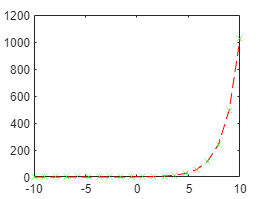

x = linspace(-10, 10, 20);
y = 2.^x;
plot(x, y, '--r', x, y, 'gX')

2. Use 2 subplots above and below each other to plot both sin(*x*) and cos(*x*) between -2π and 2π. Customise the plots any way you like.

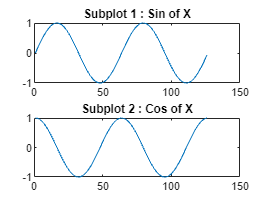

x2 = -2*pi:0.1:2*pi;
plt = subplot(2,1,1);
plot(plt, sin(x2))
title('Subplot 1 : Sin of X')
plt2 = subplot(2,1,2);
plot(plt2,cos(x2))
title('Subplot 2 : Cos of X')

3. Plot the following data in a pie chart and explode the Honda and Mercedes segments.

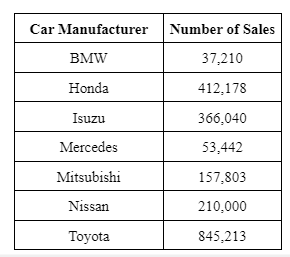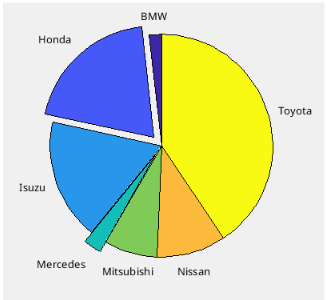

plt3 = subplot(1,1,1);
lab = {'BMW', 'Honda', 'Isuzu', 'Mercedes', 'Mitsubishi', 'Nissan', 'Toyata'};
explode = [1, 1, 1, 1, 1, 1, 1];
noSales = [37210, 412178, 366040, 53442, 157803, 210000, 845213];

pie(noSales, explode, lab)

4. Plot 

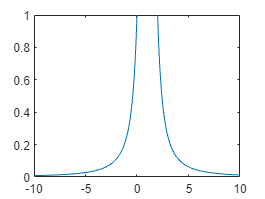

x4 = -10:0.1:10;
y4 = 1./((x4-1).^2);
plot(x4, y4)
ylim([0,1])

5. Create a character array called ***x*** that contains the first 6 letters of the alphabet. The vector should contain 6 separate character elements.

x5 = ['a', 'b', 'c', 'd', 'e', 'f'];

6. Display every odd element in the command window with a 2 second pause in between

for n = 1:length(x5)
    if mod(n,2) == 1
        fprintf(x5(n))
    end
    %pause(2);
end

ace

7. Create a 3 `x` 3 string matrix called ***A*** containing the first 9 letters of the alphabet.

A = ['a', 'b', 'c' ; 'd', 'e', 'f'; 'g', 'h', 'i'];

8. Print the diagonal entries of ***A*** with a 3 second pause in between.

for n = 1:length(A)
    fprintf(A(n, n))
    %pause(3);
end

aei

9. Create a 1 `x` 8 vector of random integers called *y*.

y9 = randi(10, 1, 8);

10. Write a for loop that replaces elements of *y* that have an even value with 0 and elements that have an odd value with 1.

y10 = y9

y10 =      9    10     2    10     7     1     3     6


for n = 1:length(y10)
    if mod(n,2) == 1
        y10(n) = 1;
    else
        y10(n) = 0;
    end
end

y10

y10 =      1     0     1     0     1     0     1     0


11. Create a 6 `x` 1 vector of random integers between 20 and 50 called *z*.

z = randi([20, 50], 6, 1)

z =     49
    49
    24
    50
    49
    35


12. Write a for loop that subtracts 12 from an element of *z* that has a value between 27 and 43.

for n = 1:length(z)
    if (27 < n) < 43
        z(n) = z(n) - 12;
    end
end
z

z =     37
    37
    12
    38
    37
    23


13. Write a for loop that doubles the 2nd, 4th and 5th entries of *y*.

y13 = y9;
for n = 1:length(y13)
    if n == 2 || n == 4 || n == 5
        y13(n) = y13(n) * 2;
    end
end
y13

y13 =      9    20     2    20    14     1     3     6


14. Repeat the task in question 13 **without using a loop** (just vector notation).

y14 = y9;
y14(2) = y14(2) * 2;
y14(4) = y14(4) * 2;
y14(5) = y14(5) * 2;

y14

y14 =      9    20     2    20    14     1     3     6


15. Write a while loop that multiplies a number by 2 until the answer is greater than 100. Test your code with numbers of your choice.

n = 1;
while n < 100
    n = n * 2;
end
n

n = 128

16. Write a while loop that decreases a number by 10 until it is less than 0.

n16 = 100;
while n16 >= 0
    n16 = n16 - 10;
end
n16

n16 = -10

17. Write a function that accepts a number as an argument. Check if it is positive or negative. If it is positive then double it, if it is negative then halve it. Return the value. Remember to give your function a descriptive name.

doubleHalf(-1)

ans = -0.5000

18. Write a function that accepts a number as an argument. Check if it is even or odd. If it is even, add 1 to it. If it is odd, subtract 1 from it. Return the value. 

addSub(2)

ans = 3

19. Write a function that accepts 2 numbers as arguments. Check if they are equal to each other. If they are, then add them. If they are not, then return the absolute value of their difference.

addAbs(3,2)

ans = 1

20. Write a function that accepts 2 numbers as arguments. If their sum is not equal to 10 then return false. If it is equal to 10, return true. 

tenTru(5,6)

ans = logical
   0


21. Write a function that accepts 3 numbers as arguments. Add the largest 2 numbers together. Return the result.

addThree(6,4,5)

ans = 11

22. Write a function that accepts 3 numbers as arguments. Subtract the smallest number from the largest. Return the result.

subLargeSmall(1, 2, 3)

ans = 2

23. Write a function that accepts a vector as an input argument. The function should print the number of elements of the input vector as well as its smallest 2 values. If the vector has less than 2 elements the function should tell the user it requires more inputs.

Functions Definition

% Q17

function a17 = doubleHalf(n)
    if n > 0
        a17 = n * 2;
    else
        a17 = n / 2;
    end
end

% Q18
function a18 = addSub(n)
    if mod(n,2) == 0
        a18 = n + 1;
    else
        a18 = n - 1;
    end
end

% Q19
function a19 = addAbs(n,m)
    if n == m
        a19 = n + m;
    else
        a19 = abs(n - m);
    end
end

% Q20
function a20 = tenTru(n,m)
    if n + m == 10
        a20 = true;
    else
        a20 = false;
    end
end

% Q21
function a21 = addThree(n,m,o)
    arr = sort([n, m, o], 'descend');
    a21 = arr(1) + arr(2);
end

% Q22
function a22 = subLargeSmall(n,m,o)
    arr = sort([n, m, o], 'descend');
    a22 = arr(1) - arr(end);
end

% Q23
function fOut = vecSmall()